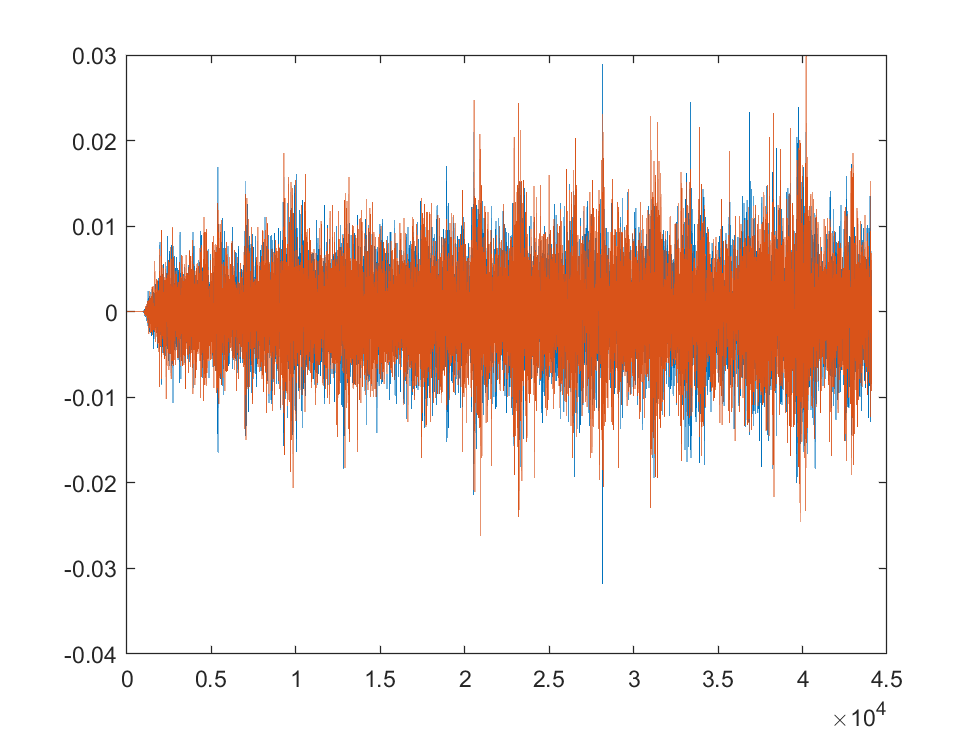

错误使用 audioread (line 155)
由于出现意外错误，无法读取文件。原因:  Reason: 没有为此流或其所依靠的流设置有效的类型。

tic
interval = 44100;
need_exist = false;
index = 1;
while ~need_exist
    try
        [x, fs] = audioread( 'Nature_s Path.aac' , [(index-1)*interval+1, index*interval ]);
    catch
        [x, fs] = audioread( 'Nature_s Path.aac' , [(index-1)*interval+1, inf ]);
        need_exist = true;
    end
    index = index + 1;
    plot(x)
    drawnow
%     pause(0.)
end

toc